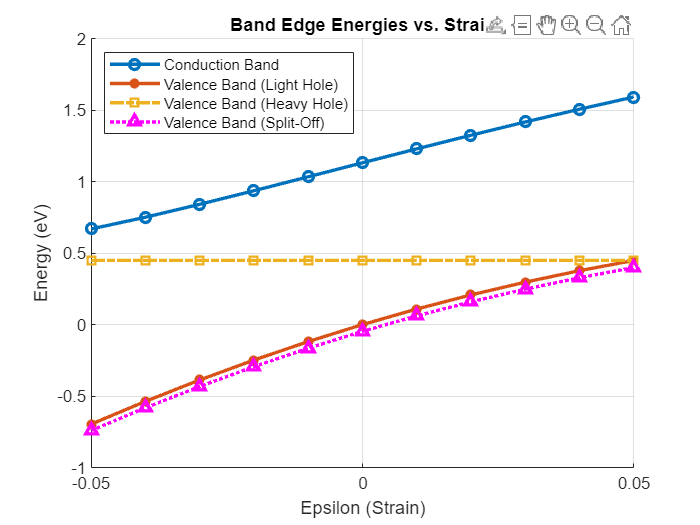

% Define the data for Epsilon and the corresponding Energies
epsilon = [-0.05, -0.04, -0.03, -0.02, -0.01, 0, 0.01, 0.02, 0.03, 0.04, 0.05];

% Conduction band edge vs. strain
energy_conduction = [0.669112, 0.751349, 0.841599, 0.936614, 1.03404, 1.13218, 1.22955, 1.32501, 1.41767, 1.50692, 1.59232];

% Valence band edge (light hole) vs. strain
energy_valence_light = [-0.69645, -0.537137, -0.387544, -0.248064, -0.118883, -1.77704e-06, 0.108724, 0.207562, 0.296875, 0.377097, 0.448712];

% Valence band edge (heavy hole) vs. strain
energy_valence_heavy = [0.448712, 0.448712, 0.448712, 0.448712, 0.448712, 0.448712, 0.448712, 0.448712, 0.448712, 0.448712, 0.448712];

% Valence band edge (split-off) vs. strain
energy_valence_split = [-0.74088, -0.582066, -0.433005, -0.294084, -0.165477, -0.0471794, 0.0609613, 0.159219, 0.24796, 0.327624, 0.398699];

% Create a plot
figure;
hold on; % Hold on to plot multiple datasets in one figure

plot(epsilon, energy_conduction, '-o', 'LineWidth', 2, 'DisplayName', 'Conduction Band');
plot(epsilon, energy_valence_light, '-*', 'LineWidth', 2, 'DisplayName', 'Valence Band (Light Hole)');
plot(epsilon, energy_valence_heavy, '-.s', 'LineWidth', 2, 'DisplayName', 'Valence Band (Heavy Hole)');
plot(epsilon, energy_valence_split, 'm:^', 'LineWidth', 2, 'DisplayName', 'Valence Band (Split-Off)');

xlabel('Epsilon (Strain)');
ylabel('Energy (eV)');
title('Band Edge Energies vs. Strain');
legend('Location', 'northwest');
legend('show');
grid on;

hold off; % Release the figure